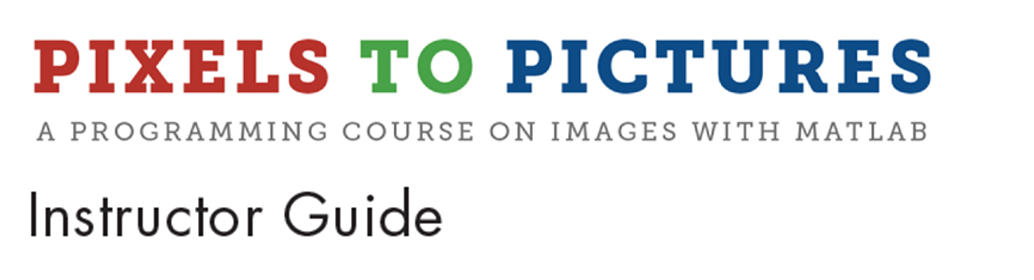

# Module 4: Indexing and Matrices

**Prerequisite Domain Knowledge:** Basic MATLAB operations, variable assignment

**Expected Completion Time: **50 minutes

## Creating and Indexing Vectors and Matrices

*Expected Duration: 30 minutes*

### Learning Objectives

- Create 1-D vector variables, both manually and using the colon operator.

- Create 2-D matrix variables.

- Extract data stored in vectors and matrices using indexing.

### Materials

- MATLAB®

### **Steps**

#### **Part I: Creating Vectors and Matrices**

Tell the students that we know the pixels in an image are arranged in rows and columns and each pixel has one color represented by RGB, so let’s explore what that means in MATLAB. 

Ask the students to open the following script:

 
open 'CreatingVectors.mlx'

Now let’s start with the more basic concept first – pixels arranged in row column format. 

Ask:

- *How might we represent this in MATLAB?  *

-     Students should mention that the pixels will need to be arranged in a row.

Show students that to create a ROW of numbers, we use square brackets [ ] at the beginning and end of your array.

We will create a variable `lucky` that contains the numbers 7, 8, 11, and 16 (as shown below):

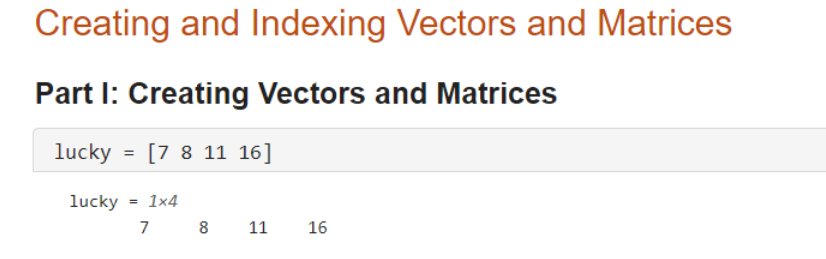

Ask:

- *How many rows are in this array?*

- *How many columns are in this array?*

-     Students should come to the conclusion that the variable `lucky` has a dimension or size of 1x4, meaning it has 1 row and 4 columns and is called a ROW VECTOR. A vector is a one-dimensional array of numbers.

If we wanted to create a COLUMN with the same numbers, we do the same thing as above, but separate each number with a semicolon (;). 

- Create a variable named “radish”:

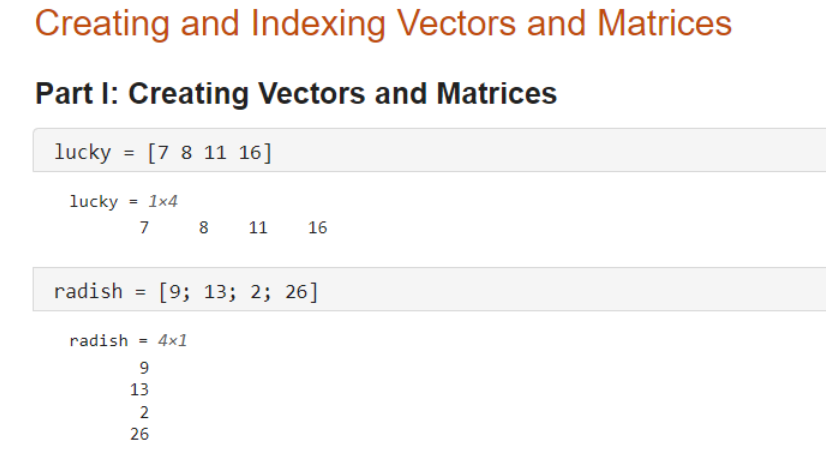

- Students should notice that this creates a variable of size 4x1, which means it has 4 rows and 1 column as expected.

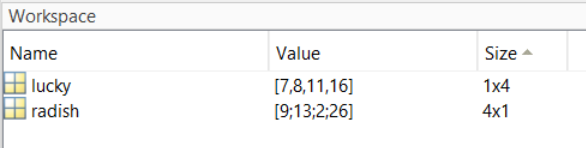

**Have the students follow along with the rest of the activity using the Live Script provided, running one section at a time using the **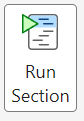** button, or by clicking the blue bar next to the section.**

If you want to create a long list of numbers, you can use the colon operator. 

- The syntax for this is:   Starting-number   COLON  step-size  COLON  ending-number

- This syntax tells you to start at 0, go up by one each time, and end at 8.

- Instruct students to create a few more vectors.  Give the students 5-10 minutes to explore changing the parameters for each vector. For each of these vectors, ask the following questions. For example, 

- *How many elements (numbers) long do you think each will be?  *

-     R will have 5 elements (3 3.5 4 4.5 5), S will have 3 elements (4 6 8).

- *What will be the final number for these vectors?  *

-     The final number of R will be 5.  The final number of S will be 8.

- *What will happen if the second number is not included in the command?  *

Students should notice that the numbers will increase with a step of 1.

Explain to students that when the step size is 1, you do not need the number in the middle. If you leave that number off, by default MATLAB will assume you wanted a step size of 1.   Let’s try using variables as the parameters for another vector.  Instruct students to assign two variables and use them as the parameters for a new vector.  (See below for an example)

Tell students that there is a useful command that allows you to flip a row vector to a column vector, or vice versa.   All you need to do is add a single apostrophe at the end of the vector. (‘) 

This is called transposing the vector.

Encourage the students to create their own vectors using the colon operator.  

Ask:

- *Can the step sizes be negative? For example, what if we created a vector called, “reverse”?*

Now that they have a good understanding of 1-D arrays, lets see how we can combine them to create a variable with both rows and columns. To do this, we have to use a combination of spaces and semicolons, as shown below

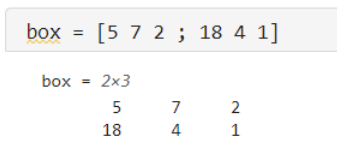

- We can see a variable `box` in the **Workspace** which has a size of 2x3 – 2 rows and 3 columns. Spaces create a new column (place new number on the side) and semicolons create new rows (place number in new line).

If a variable has more than 1 rows and columns, it is called a two dimensional array or a MATRIX.  

Ask:

- *How can we make a matrix with the first row containing the values “5, 7, 2” and the second row containing “18, 4, 1”?  *

-     Encourage students to determine the correct command line for this and then test it.

- *What would result from the following command line?*

- This would create an error!  One row has 3 numbers and the second row has two numbers.  Explain to students that a matrix is like a rectangular box, every row needs to have the same number of columns – like an image!

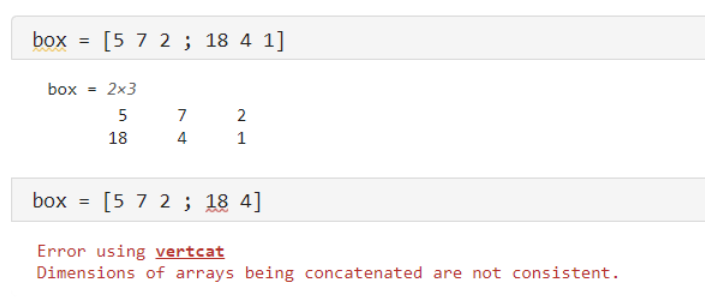

#### **Part II: Indexing into Vectors and Matrices**

Tell students that oftentimes we are interested in only a portion of our array dataset. For example, you might want only a small portion of an image.  We will explore how to extract portions of our vectors and matrices.

Create a vector, named “dice”, that contains all of the number of a die:

Here `roll` returns the third element in the vector `dice` - 4.   

Let the students know that they can index more than one number at a time. Inside the parentheses, input the desired indices with square brackets as a vector. Even though you are giving more than one indexing number, you are still giving only one argument for indexing—namely, the indexing vector.

Ask:

- *What would the code for the odd numbers of x be?*

- If you want to get a sequence of numbers that are in all in a row, use the colon operator when indexing.

This tells MATLAB to get the first through the fifth numbers.

This tells MATLAB to get the sixth through the tenth numbers.  

Ask:

- How would you describe this command line? What are we asking MATLAB to do in this code?  

-     Students should mention that the `bignumbers` variable asks  MATLAB to get the sixth element all the way to the end. 

If you get all the elements up to the end, there is a special syntax for this.  Use the keyword end in place of the final number. 

Ask:

- *Do you think that we can use the same type of command line to index a matrix?  *

-     Accept all reasonable answers from students.  Students should note that since vectors are 1-D, there is only one way to count to the 4th element. However, for a matrix (2-D), saying we want the 4thelement can lead to questions like, do you want the 4th element in the row or the 4th element in the column. 

To be explicit, when extracting an element from a matrix we need to specify both the row and column number.

Instruct students to create a matrix:

Double click on the variable `matrix `in the **Workspace.** This will open the variable up in the **Variable Editor**. 

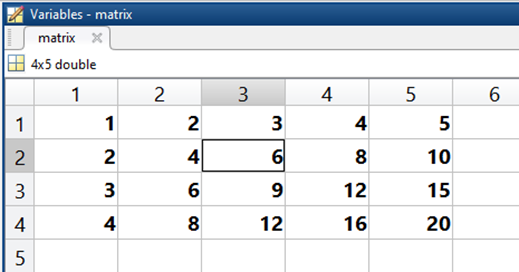

If we wanted to extracted the 6 shown above, how would we do it? The number is in the 2nd row and 3rd column of the matrix, so the syntax will be

Ask:

- *How might you extract the number 15 (3rd row, 5th column)?  *

-     Students should mention that we have to tell MATLAB to find the number in row 3 and column 5.

Since 15 is in the last column, the following syntax will also work

Now how would we extract more than one element?

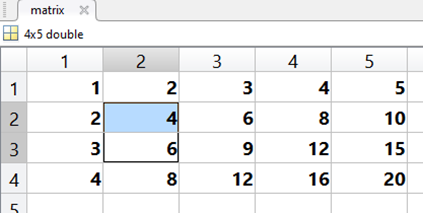

The concept is the same. Here we are extracting elements that are in rows 2 and 3 and column 2

Or

Here is another example. We want to extract rows 2 to 4 and columns 4 and 5.

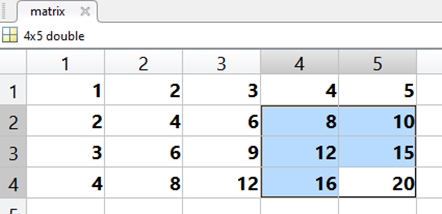

Finally, how would we extract a complete row or column from a matrix. 

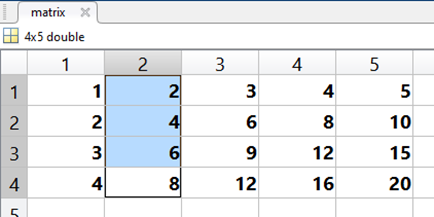

We want to extract all the rows in the 2nd column

Or

Or

- When the colon operator is used by itself, it means all row or all columns.

Ask them how they could extract the following

Give students a few minutes to practice extracting different combinations of number from this matrix. Drive home the fact that when indexing, we should ALWAYS provide the rows first, then the columns.

To wrap up this activity, gather students and ask:

- *What interesting things did you learn about arrays, vectors, and matrices?*

- *Can you think of any real life situations where we might use vectors and/or matrices?  *

-     Students should revisit the idea that images are matrices of pixels.  Students may mention other things like a crossword puzzle, Sudoku, etc. 

- *How might indexing a vector or matrix be helpful?  *

-     Accept all reasonable answers.

## Playing Word Search

*Expected Duration: 20 minutes*

### Learning Objectives

- Students practice indexing in a fun setting by searching and extracting words from a word matrix.

### Materials

- MATLAB®

### **Steps**

Guide the students to the **APPS** tab in MATLAB and ask them to open the WordSearch app.

                               

Ask:

- *Why can we look at a word search puzzle as a matrix?*

- *What skill(s) have you learned that might be useful in solving a word search with MATLAB?*

- *How might we be able to instruct MATLAB to find the words listed under “Words to find”? *

-     Students should mention that they can do this by indexing into the appropriate rows and columns of the words. 

Guide students through finding one word.  For example, the word CRAB (2nd word in the list) can be found in the 4thcolumn along rows 1 to 4, so type in the following in the two edit boxes in the app:

And press **Enter** to get

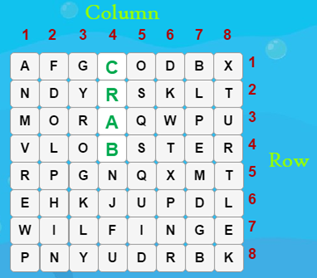

Let the students know that they will have 15 minutes to find the remaining words.

Tell students that if they make a mistake, they can click on the “Reset Errors’ button to fix it and they can click on the “Show Example” button to look at the syntax.

There is also a timer provided if students want to see how quickly they can complete the Word Search. They can choose to hide the timer if they don't want to see it. 

At the end of 15 minutes, gather students to share their solutions for each word.

**Solution:**

- **COD →  **`>>` `ocean ( 1 , 4:6 )`

- **CRAB → **`>>` `ocean( 1:4 , 4 )`

- **DOLPHIN** **→ **`>>` `ocean( 2:8 , 2 )`

- **FIN** **→ **`>>` `ocean( 7 , 4:6 )`

- **LOBSTER** **→ **`>>` `ocean( 4 , 2:8 )`

- **SQUID→ **`>>` `ocean( 4:8 , 5 )`

- **TURTLE** **→ **`>>` `ocean( 2:7 , 8 )`

Ask:

- *What challenges did you run into while solving the word search?*

- *Where there strategies that helped you be more successful?  *

-     Students may mention that copying and pasting parts of the code helped them work faster or more efficiently

© COPYRIGHT 2024 by The MathWorks®, Inc.